# Q7 ) MATLAB

##  Yunus Talha ERZURUMLU 2443018

### Part 1,Part 2 and Part 3 Given Together

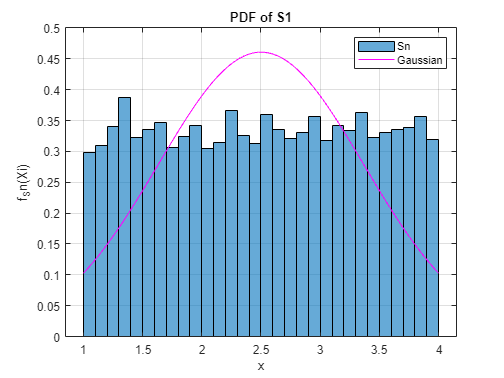

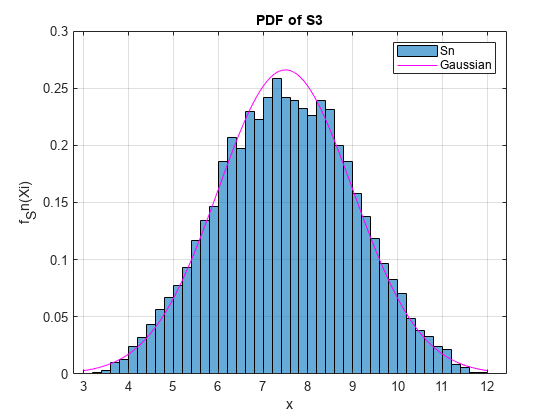

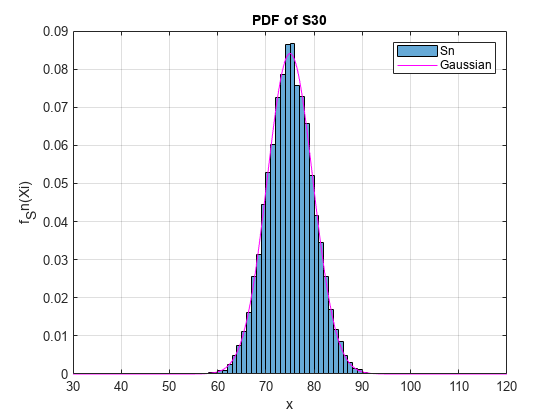

clc, clear, close all % clear the console, workspace and close all figures
rng('shuffle') % initialize the random number generator with a new seed

% Define the range of values for the uniform distribution and the sample size
uniformity_range = [1, 4];
uni_diff = uniformity_range(2) - uniformity_range(1);
sample_size = 1e4;

% Define the values of n for which to plot the histograms
n_set = [1,3,30];
n_set_size = numel(n_set);

% Define the range of values for which to plot the probability density function
A_range = uniformity_range(1):0.01:uniformity_range(2);

% Calculate the mean and variance of the uniform distribution
mean_ = (uniformity_range(1) + uniformity_range(2)) / 2;
variance_ = uni_diff^2 / 12;

% Generate a matrix A with n_set(n_set_size) rows and sample_size columns, where each
% row contains the cumulative sum of random numbers drawn from the uniform distribution
A = cumsum(uni_diff .* rand(n_set(n_set_size), sample_size) + uniformity_range(1)); % Every row of this 

% Loop through each value of n in n_set
for i = 1:n_set_size
    n = n_set(i);
    
    % Plot the histogram of the nth row of A
    figure
    histogram(A(n,:), 'Normalization', 'pdf')
    hold on
    
    % Define parameters for the Gaussian distribution to plot
    n_A_range = n .* A_range;
    n_mean = n * mean_;
    n_variance = n * variance_;
    n_sigma = sqrt(n_variance);
    gaussian = normpdf(n_A_range, n_mean, n_sigma);
    
    % Plot the Gaussian distribution on the same graph as the histogram
    plot(n_A_range, gaussian, 'Color', 'magenta')
    
    % Add a title, axis labels, and legend to the graph
    title(sprintf('PDF of S%d', n))
    xlabel('x')
    ylabel('f_Sn(Xi)')
    legend('Sn','Gaussian')
    grid on
end

    "Mean of S1 : 2.5 Variance of S1 : 0.75"



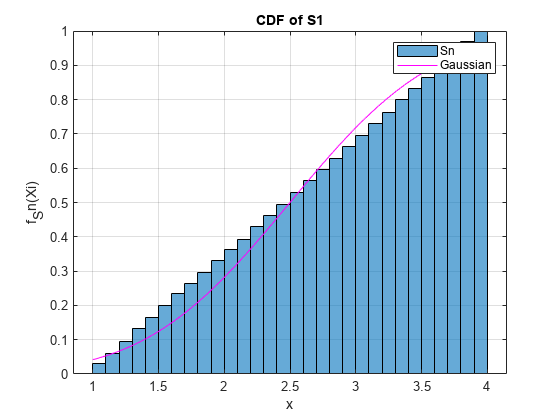

    "Mean of S3 : 7.5 Variance of S3 : 2.25"



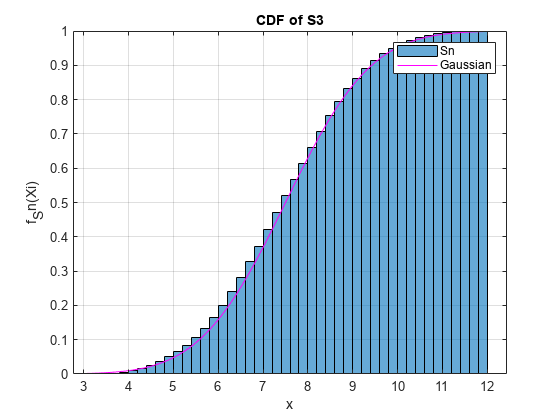

    "Mean of S30 : 75 Variance of S30 : 22.5"



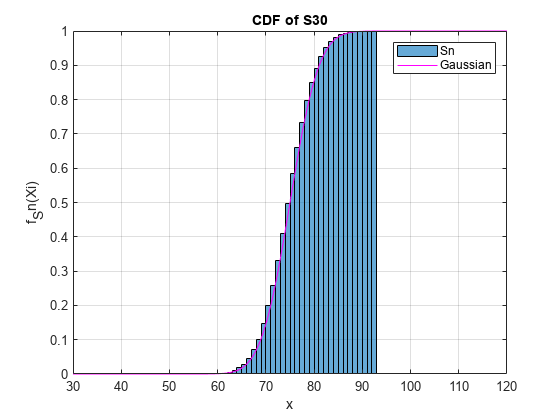


for i = 1:n_set_size
    n = n_set(i);

    % Plot the histogram of the nth row of A
    figure
    histogram(A(n,:), 'Normalization', 'cdf')
    hold on

    % Define parameters for the Gaussian distribution to plot
    n_A_range = n .* A_range;
    n_mean = n * mean_;
    n_variance = n * variance_;
    display("Mean of S" + (num2str(n)) + " : " + (num2str(n_mean)) + " Variance of S" + (num2str(n)) + " : " + (num2str(n_variance)))
    n_sigma = sqrt(n_variance);
    gaussian = normcdf(n_A_range, n_mean, n_sigma);
    
    % Plot the Gaussian distribution on the same graph as the histogram
    plot(n_A_range, gaussian, 'Color', 'magenta')
    
    % Add a title, axis labels, and legend to the graph
    title(sprintf('CDF of S%d' , n))
    xlabel('x')
    ylabel('f_Sn(Xi)')
    legend('Sn','Gaussian')
    grid on
end

#### Part D

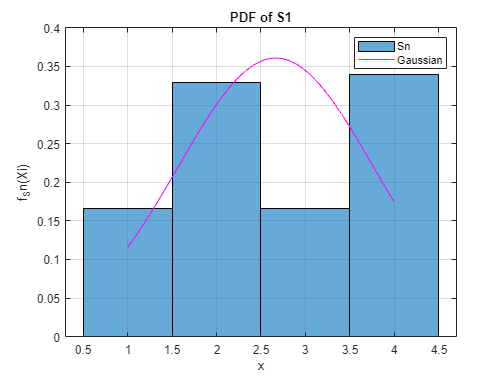

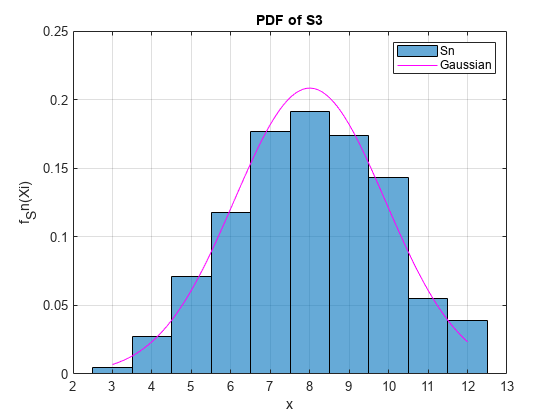

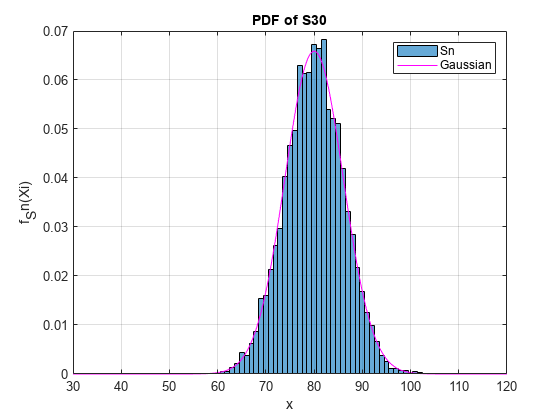


clc, clear, close all
rng('shuffle')

% Part (d)
sample_size = 1e4;
p_even = 1/3;
p_odd = 1/6;

n_set = [1,3,30];
n_set_size = numel(n_set);

% Analytical Mean and Variance of X
X_mean = (1*p_odd + 2*p_even + 3*p_odd + 4*p_even);
X_variance = ((1-X_mean)^2)*p_odd + ((2-X_mean)^2)*p_even + ((3-X_mean)^2)*p_odd + ((4-X_mean)^2)*p_even;

% Analytical Mean and Variance of S_n
S_n_mean = n_set*X_mean;
S_n_variance = n_set*X_variance;

% Generate S_n
S_n = zeros(30, sample_size);
for i = 1:sample_size
    X = randsample([1,2,3,4],30,true,[p_odd,p_even,p_odd, p_even]);
   S_n(:,i) = cumsum(X);
end

% Plot PDF and CDF of S_n

for i = 1:n_set_size
    n = n_set(i);
    figure
    histogram(S_n(n,:), 'Normalization', 'pdf')
    hold on
    x_values = linspace(n*1, n*4, 1000);
    y_values = normpdf(x_values, S_n_mean(i), sqrt(S_n_variance(i)));
    plot(x_values, y_values, 'Color', 'magenta')
    title(sprintf('PDF of S%d', n))
    xlabel('x')
    ylabel('f_Sn(Xi)')
    legend('Sn','Gaussian')
    grid on

end

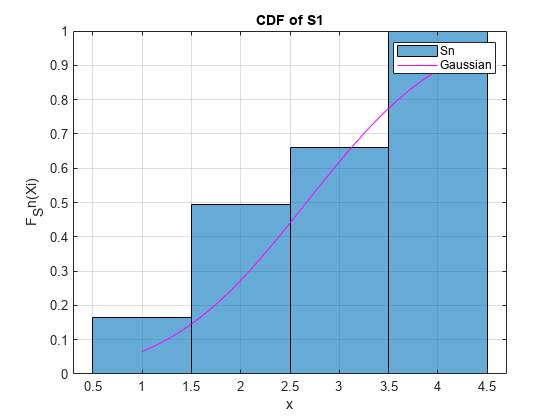

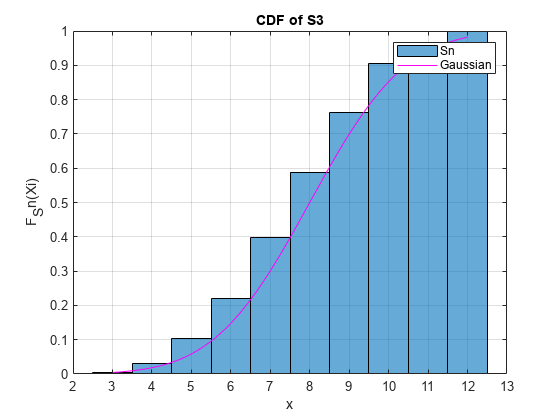

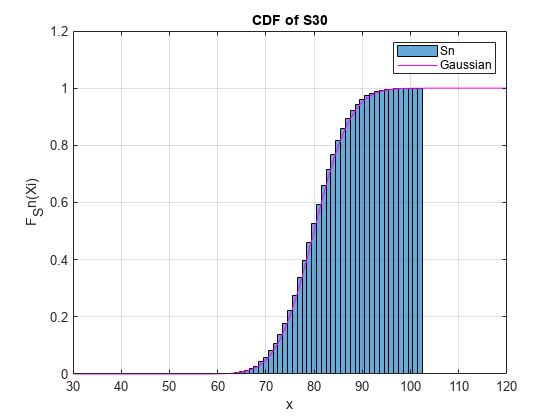


for i = 1:n_set_size
    n = n_set(i);
    figure
    histogram(S_n(n,:), 'Normalization', 'cdf')
    hold on
    x_values = linspace(n*1, n*4, 1000);
    y_values = normcdf(x_values, S_n_mean(i), sqrt(S_n_variance(i)));
    plot(x_values, y_values, 'Color', 'magenta')
    title(sprintf('CDF of S%d', n))
    xlabel('x')
    ylabel('F_Sn(Xi)')
    legend('Sn','Gaussian')
    grid on

end

As seen from both examples when n becomes larger, PDF and CDF becomes like Gaussian even for different distrubuitions. 